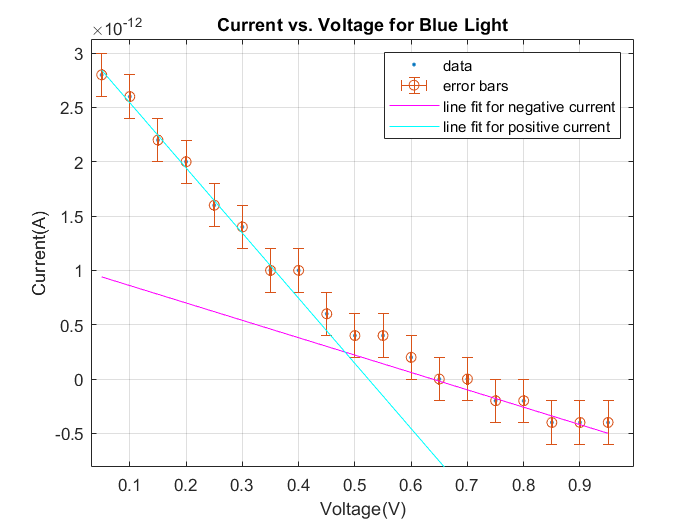

plot(BLUEvoltage,BLUEcurrent,'.')
hold on,


%%CREATING ERRORBARS
xneg=0.001.*[1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1];
xpos=xneg;
yneg=(0.2e-12).*[1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1];
ypos=yneg;
errorbar(BLUEvoltage,BLUEcurrent,yneg,ypos,xneg,xpos,'o')



%%NEGATIVE SIDE FIT
%Linear model Poly1:
 %    f(x) = p1*x + p2
%Coefficients (with 95% confidence bounds):
 %      p1 =    -1.600E-12  (-4.034e-12, 8.339e-13)  (\pm 1.217E-12)
  %     p2 =    1.020E-12  (-9.926e-13, 3.033e-12)  (\pm 1.006E-12)

%Goodness of fit:
 % SSE: 8e-27
  %R-square: 0.8
  %Adjusted R-square: 0.7
  %RMSE: 6.325e-14
  p1 =    -1.6e-12;
  p2 =    1.02e-12 ;
   f=p1.*BLUEvoltage+p2;
   
   plot(BLUEvoltage,f,'m')
   
%%POSITIVE SIDE FIT
%Linear model Poly1:
%     f(x) = p3*x + p4
%Coefficients (with 95% confidence bounds):
%       p3 =      -6.000E-12  (-6.569e-12, -5.431e-12)  (\pm 0.284E-12)
%       p4 =   3.143E-12  (3.016e-12, 3.27e-12)     (\pm 0.064E-12)

%Goodness of fit:
%  SSE: 1.714e-26
%  R-square: 0.9932
%  Adjusted R-square: 0.9919
%  RMSE: 5.855e-14
 p3 =      -6e-12;
 p4 =   3.143e-12 ;
 g = p3.*BLUEvoltage + p4;
 plot(BLUEvoltage,g,'c')
 
 grid on
xlim([0.031 0.996])
ylim([-0.00000000000081 0.00000000000313])
title('Current vs. Voltage for Blue Light')
xlabel('Voltage(V)')
ylabel('Current(A)')
legend({'data','error bars','line fit for negative current','line fit for positive current'})